Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

cd(Temperature_path)
load('saved_rawDataName.mat')

rawData_all = ([Temperature_path,'rawData_all_0920.mat'])

rawData_all = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/rawData_all_0920.mat'

OptResults_all =([Temperature_path,'OptResults_all_0920.mat'])

OptResults_all = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/OptResults_all_0920.mat'

global middle_inputs
middle_inputs = {};

load(OptResults_all)
% Define initial input
initial_temperature = 4.1365; % negative value produces an estimated initial temperature
minutesToInitialT = 5;
SF=4;

% Use the median parameter values from Table 1:
p.sizePWP = OptimizedParameters.sizePWP;              % window size (in hours) of the prior wake prevelance (PWP)
p.shiftPWP = OptimizedParameters.shiftPWP;          % window shift (in hours) of the prior wake prevelance (PWP)
p.lowerAsymptote = OptimizedParameters.lowerAsymptote;   % Lower asymptote value (in C)
p.upperAsymptote =  OptimizedParameters.upperAsymptote;  % Upper Asymptote value (in C)
p.wakeTimeConstant = OptimizedParameters.wakeTimeConstant;  % Time constant of wake and REM states
p.nremTimeConstant = OptimizedParameters.nremTimeConstant;  % Time constant of NREM sleep
p.scalePWP = OptimizedParameters.scalePWP;          % The multiplier of PWP values
p.circadianAmplitude = OptimizedParameters.circadianAmplitude;% The multiplier of the circadian values
p.circadianPhase = OptimizedParameters.circadianPhase;   % Phase shift of circadian process (in hours)

% load(rawData1)
load(rawData_all)
flagsWakeREM = states_pooled;

global mean_asyPWP
mean_asyPWP =[];

[simulatedT_all,asymptots] = simulateBrainTemperature (...
        flagsWakeREM, initial_temperature,circadian_time,1, SF, p.sizePWP, p.shiftPWP,...
        [p.lowerAsymptote, p.upperAsymptote, p.wakeTimeConstant, ...
         p.nremTimeConstant, p.scalePWP, p.circadianAmplitude, p.circadianPhase...
        ]);

middle_inputs_all = middle_inputs;

ignored_index = find(circadian_time >= 10800 & circadian_time< 10800+2700);
tau_pooled(ignored_index) = [];
correlation = corr(tau_pooled,simulatedT_all)

correlation =    0.797847672400758


figure
plot(simulatedT_all)
hold on
plot(simulatedT)

load(rawData1)
flagsWakeREM = states_pooled;
initial_temperature = 4.14

initial_temperature = 4.1400

[simulatedT1,asymptots] = simulateBrainTemperature (...
        flagsWakeREM, initial_temperature,circadian_time,1, SF, p.sizePWP, p.shiftPWP,...
        [p.lowerAsymptote, p.upperAsymptote, p.wakeTimeConstant, ...
         p.nremTimeConstant, p.scalePWP, p.circadianAmplitude, p.circadianPhase...
        ]);

ignored_index = find(circadian_time >= 10800 & circadian_time< 10800+2700);
tau_pooled(ignored_index) = [];
correlation = corr(tau_pooled,simulatedT1)

correlation = 0.5864

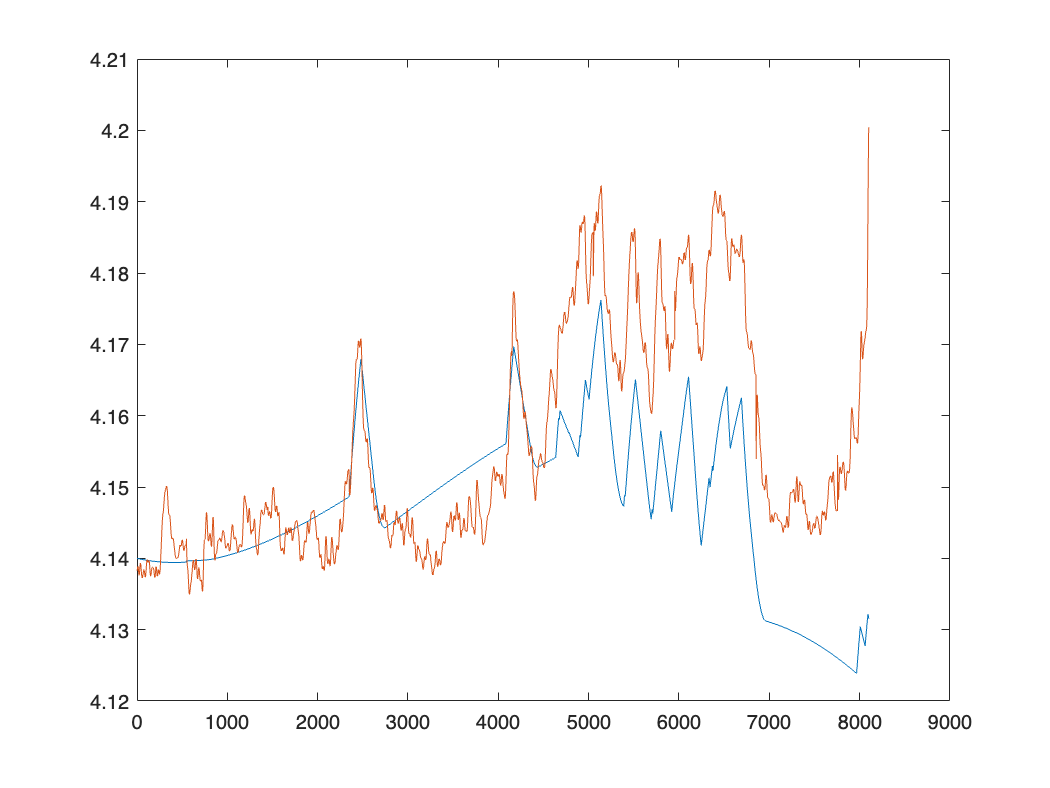

figure
plot(simulatedT1)
hold on
plot(tau_pooled)

middle_inputs1=middle_inputs;

figure
plot(middle_inputs1{1}, middle_inputs_all{1}(1:8100))


figure
plot(middle_inputs1{2}, middle_inputs_all{2}(1:8100))


figure
plot(middle_inputs1{3}, middle_inputs_all{3}(1:8100))

sum(middle_inputs1{1}-middle_inputs_all{1}(1:8100))

ans =      0


sum(middle_inputs1{2}-middle_inputs_all{2}(1:8100))

ans =      0


sum(middle_inputs1{3}-middle_inputs_all{3}(1:8100))

ans =      0


load(OptResults1)
% Define initial input
initial_temperature = 4.14; % negative value produces an estimated initial temperature
SF=4;

% Use the median parameter values from Table 1:
p.sizePWP = OptimizedParameters.sizePWP;              % window size (in hours) of the prior wake prevelance (PWP)
p.shiftPWP = OptimizedParameters.shiftPWP;          % window shift (in hours) of the prior wake prevelance (PWP)
p.lowerAsymptote = OptimizedParameters.lowerAsymptote;   % Lower asymptote value (in C)
p.upperAsymptote =  OptimizedParameters.upperAsymptote;  % Upper Asymptote value (in C)
p.wakeTimeConstant = OptimizedParameters.wakeTimeConstant;  % Time constant of wake and REM states
p.nremTimeConstant = OptimizedParameters.nremTimeConstant;  % Time constant of NREM sleep
p.scalePWP = OptimizedParameters.scalePWP;          % The multiplier of PWP values
p.circadianAmplitude = OptimizedParameters.circadianAmplitude;% The multiplier of the circadian values
p.circadianPhase = OptimizedParameters.circadianPhase;   % Phase shift of circadian process (in hours)

load(rawData1)
flagsWakeREM = states_pooled;

[simulatedT,asymptots] = simulateBrainTemperature (...
        flagsWakeREM, initial_temperature,circadian_time,1, SF, p.sizePWP, p.shiftPWP,...
        [p.lowerAsymptote, p.upperAsymptote, p.wakeTimeConstant, ...
         p.nremTimeConstant, p.scalePWP, p.circadianAmplitude, p.circadianPhase...
        ]);

ignored_index = find(circadian_time >= 10800 & circadian_time< 10800+2700);
tau_pooled(ignored_index) = [];
correlation = corr(tau_pooled,simulatedT)

correlation = 0.9611

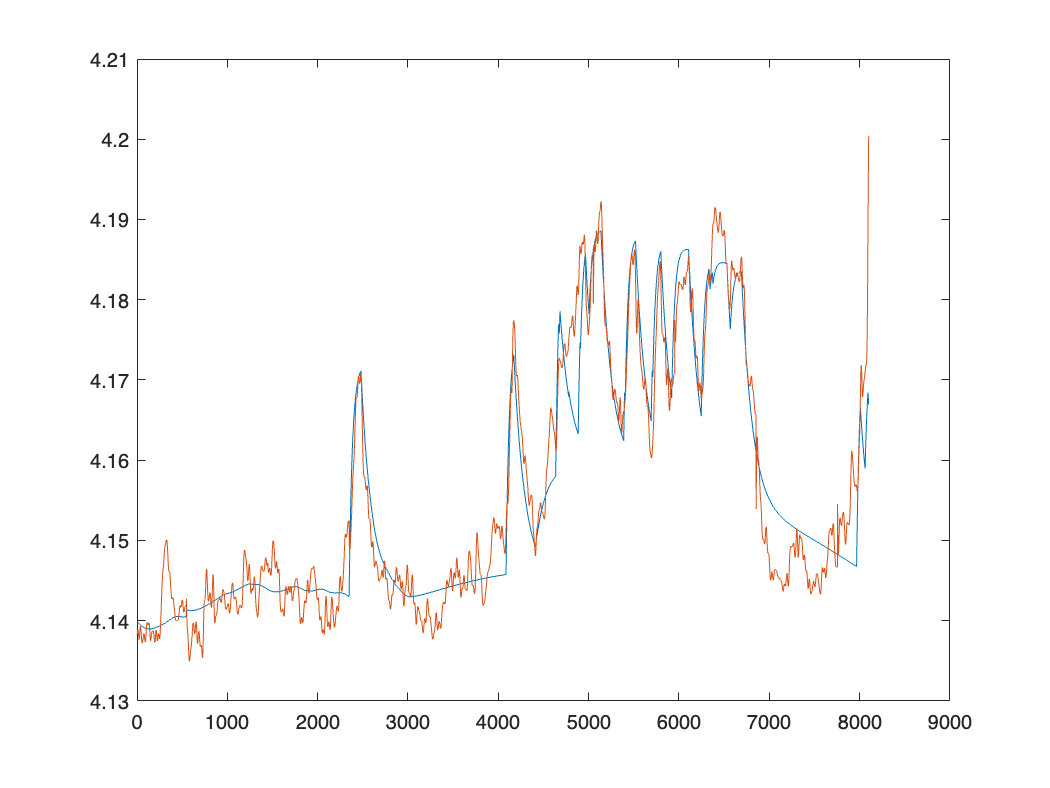

figure
plot(simulatedT)
hold on
plot(tau_pooled)

size_of_acq = [];
correlation_all = [];
size_of_acq(1)=0;
load(OptResults_all)
T_all = simulatedT;

for i = 1:4
    eval(['load(OptResults',num2str(i),')'])
    size_of_acq(i+1) = size_of_acq(i)+length(simulatedT)
end

size_of_acq =            0        8100


size_of_acq =            0        8100       16200


size_of_acq =            0        8100       16200       24134


size_of_acq =            0        8100       16200       24134       30279


correlation_all = 0.7542

correlation_all =     0.7542    0.8483


correlation_all =     0.7542    0.8483    0.8808


correlation_all =     0.7542    0.8483    0.8808    0.8006


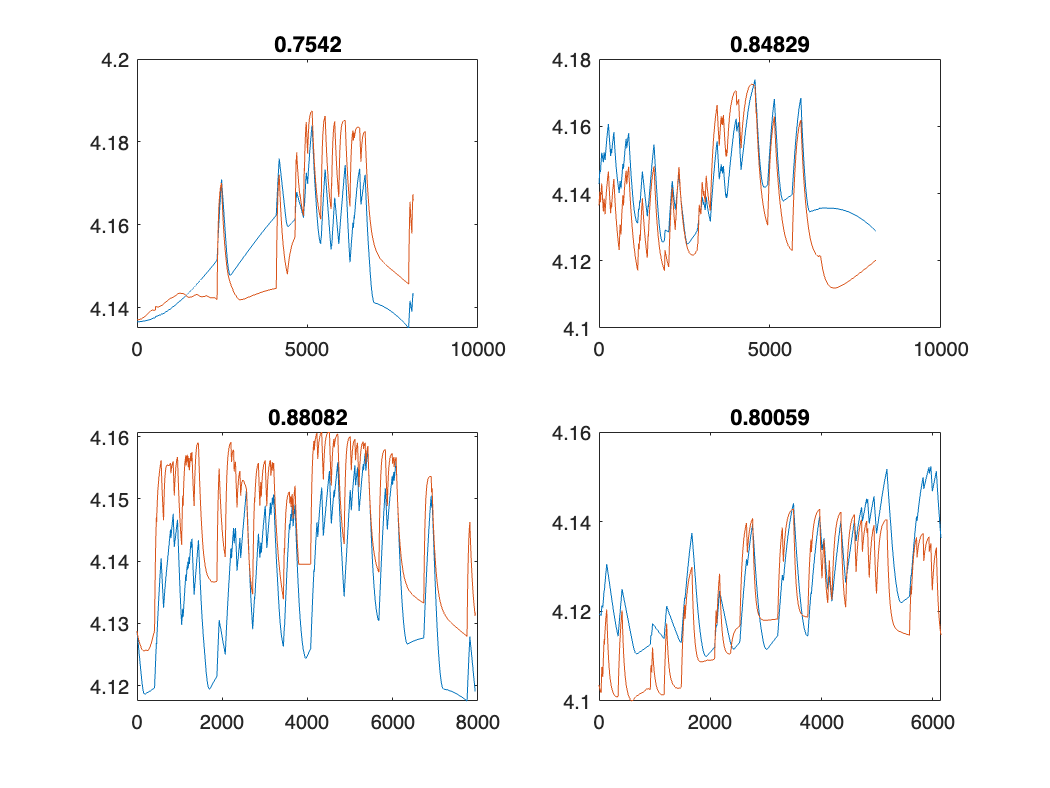


for i = 1:4
    eval(['load(OptResults',num2str(i),')'])
    correlation_all(i) = corr(T_all(size_of_acq(i)+1:size_of_acq(i+1)), simulatedT)
    subplot(2,2,i)
    plot(T_all(size_of_acq(i)+1:size_of_acq(i+1)))
    hold on
    plot(simulatedT)
    title(num2str(correlation_all(i)))
    hold off
end